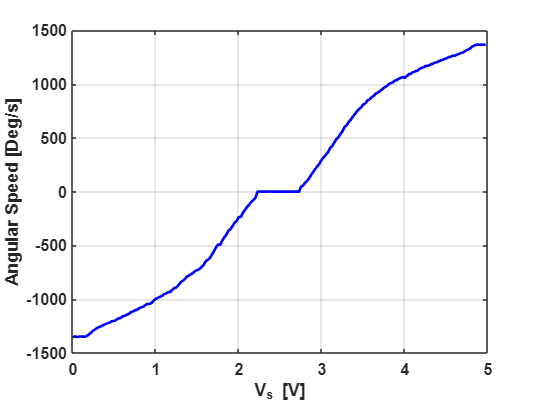

% About: Acknowldeging Static Motor Characteristics 
%                      Mapping Function
%                      Validation
% Author    : Chanjung Kim
% Created   : 24.11.26
% Modified  : 24.12.24

% Raw data plot
clear; close all; clc;

fileLength = 200;
DEAD = 2.53;

DATA = cell(fileLength,1);

addpath("C:\Users\wnd02\source\repos\DCSP\DCSP_Tutorial\DCSP_Gimbal_Motor\12.04_Static\");
% addpath("C:\Users\wnd02\Downloads\Gyro_Static_data\");

Vs = 0.025;

for k = 0 : fileLength-1
%     fileName = sprintf("Gyro_%.3fV_Voff1.34605V_data.out", Vs*k);
    fileName = sprintf("%.4f_Cha_data.out", Vs*k);
    DATA{k+1} = load(fileName);
end
% ======================== W Calculation ===============================
% graph of Vcmd Vs W
W = zeros (fileLength, 1);

for k = 1 : fileLength
    N = length(DATA{k});
    TIME = DATA{k}(:,1);
    Vgyro = DATA{k}(:,3);
    sum = 0.0;
    count = 0;
    for i = 500 : N
        sum = sum + Vgyro(i);
        count = count + 1;
    end
    W(k) = sum/count;
end

Vcmd = 0:Vs:5-Vs;
Vcmd = Vcmd';
N_VOL = length(Vcmd);
out = [Vcmd, W];

figure(1),hold on, grid on, box on, plot(Vcmd, W, 'b', LineWidth = 2);
set(gca, 'Fontsize', 12, 'FontWeight', 'bold');
ylabel('Angular Speed [Deg/s]');
xlabel('V_{s} [V]');
hold off;


% ============================= Linear Variable =========================
% graph of Vc vs W, Vc Vs Vcmd
Wmax = max(W);
Wmin = min(W);

Wmean = (Wmax-Wmin)/2;

% ALPHA = (Wmean)/(5-DEAD)
ALPHA = Wmean/2.5

ALPHA = 544.0489

BETA_P = -ALPHA*DEAD;
BETA_N = -Wmean;

Vc = zeros(N_VOL, 1);

for k = 1:N_VOL
    if (Vcmd(k) <= (5-DEAD))
        Vc(k) = (W(k)-BETA_N)/ALPHA;
    elseif (Vcmd(k) >= DEAD)
        Vc(k) = (W(k)-BETA_P)/ALPHA;
    else
        Vc(k) = 2.5;
    end
end


% ============================= Fitting =============================
% graph of fitting function

DATA_CUT = 8

DATA_CUT = 8

N_N = 90;
N_P = 110;

Vcmd_N = Vcmd(DATA_CUT:N_N, 1);
Vcmd_P = Vcmd(N_P:end-DATA_CUT,1);

Vc_N = Vc(DATA_CUT:N_N, 1);
Vc_P = Vc(N_P:end- DATA_CUT,1);

% fittype과 옵션을 설정하십시오.
ft = fittype( 'poly3' );

% 데이터에 모델을 피팅하십시오.
[f_P, gof] = fit( Vc_P, Vcmd_P, ft );

[f_N, fog] = fit( Vc_N, Vcmd_N, ft );

Bias_N = 2.23 - f_N(5-DEAD)

Bias_N = 0.0182

Bias_P = 2.747 - f_P(DEAD)

Bias_P = 0.0563

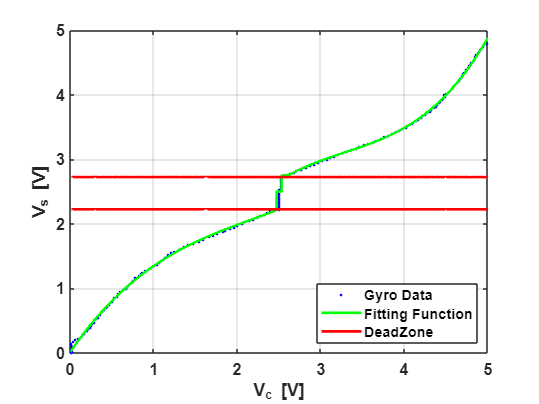


Vs = 0.001;
Vref = 0:Vs:5;
N_Vref = length(Vref);
y_n = zeros(N_Vref, 1);

for k = 1: N_Vref
    if Vref(k) <= (5-DEAD)
        y_n(k) = f_N(Vref(k));
        if (abs(DEAD-Vref(k)) < 0.1)
            scale_V = 1 - abs(DEAD - Vref(k))*10;
            y_n(k) = f_N(Vref(k)) + scale_V * Bias_N;
        end
    elseif (Vref(k) >= DEAD)
        y_n(k) = f_P(Vref(k));
        if (Vref(k) - DEAD < 0.1)
            scale_V = 1 - (Vref(k) - DEAD)*10;
            y_n(k) = f_P(Vref(k)) + scale_V * Bias_P;
        end
    else
        y_n(k) = 2.5;
    end
end
% Vc(90:100) = 2.5
figure(5), hold on , grid on, box on, plot(Vc, Vcmd, '.b', LineWidth = 2);
plot(Vref, y_n, 'g', LineWidth = 2);
plot(Vc, 2.725*ones(N_VOL), 'r', Vc, 2.225*ones(N_VOL), 'r', LineWidth = 2);
set(gca, 'Fontsize', 12, 'FontWeight', 'bold');
legend('Gyro Data', 'Fitting Function', 'DeadZone', Location='southeast');
xlabel('V_c [V]');
ylabel('V_s [V]');
xlim([0 5]);
ylim([0 5]);

% ========================== Ideal Vs Fitting ============================
% graph of scaled Vc vs Vcmd and Vc vs W
W_pp = Wmax - Wmin; 
scale_k = 5/W_pp;



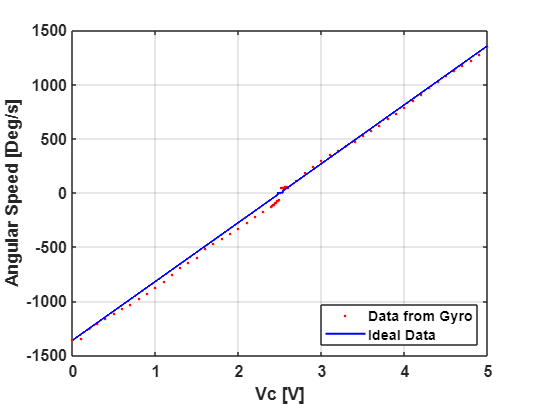

% ============================= Validation ===============================
fileLength_f = 51;
DATA_V = cell(fileLength_f,1);

addpath("C:\Users\wnd02\source\repos\DCSP\DCSP_Motor\DCSP_Motor_Lin\")
% addpath("C:\Users\wnd02\source\repos\DCSP\DCSP_Motor\DCSP_Motor_Lin\Gyro_data_tuned\")

Vs = 0.1;
Vstart = 0.0;

for k = 0 : fileLength_f-1
    fileName = sprintf("%.2f_data.out", Vs*k + Vstart);
    DATA_V{k+1} = load(fileName);
end
fileLength_s = 21;
DATA_D = cell(fileLength_s,1);

Vs = 0.01;
Vstart = 2.4;

for k = 0 : fileLength_s-1
    fileName = sprintf("%.2f_data.out", Vs*k + Vstart);
    DATA_D{k+1} = load(fileName);
end
% ======================== W Calculation ===============================
% graph of Vcmd Vs W
W_f = zeros (fileLength_f, 1);
Vc_f = zeros (fileLength_f, 1);
W_s = zeros (fileLength_s, 1);
Vc_s = zeros (fileLength_s, 1);

for k = 1 : fileLength_f
    N = length(DATA_V{k});
    TIME = DATA_V{k}(:,1);
    Vgyro = DATA_V{k}(:,3);
    Vc_f(k) = DATA_V{k}(1,4);
    sum = 0.0;
    count = 0;
    for i = 500 : N
        sum = sum + Vgyro(i);
        count = count + 1;
    end
    W_f(k) = sum/count;
end

for k = 1 : fileLength_s
    N = length(DATA_D{k});
    TIME = DATA_D{k}(:,1);
    Vgyro = DATA_D{k}(:,3);
    Vc_s(k) = DATA_D{k}(1,4);
    sum = 0.0;
    count = 0;
    for i = 500 : N
        sum = sum + Vgyro(i);
        count = count + 1;
    end
    W_s(k) = sum/count;
end

% out = [Vc_f;Vc_s, W_f; W_s];
V_ideal = zeros(N_Vref, 1);

for k = 1: N_Vref
    if (Vref(k) <= (5-DEAD))
        V_ideal(k) = ALPHA * Vref(k) + BETA_N;
    elseif (Vref(k) >= DEAD)
        V_ideal(k) = ALPHA * Vref(k) + BETA_N;
    else 
        V_ideal(k) = 0;
    end
end

W_total = [W_f;W_s];
Vc_total = [Vc_f; Vc_s];

figure, hold on , grid on , box on, plot(Vc_total, W_total, '.r', LineWidth=2);
plot(Vref, V_ideal, 'b', LineWidth= 1.5);
set(gca, 'Fontsize', 12, 'FontWeight', 'bold');
legend('Data from Gyro', 'Ideal Data', Location='southeast');
xlabel('Vc [V]');
ylabel("Angular Speed [Deg/s]");

% xlim([2 3]);
% ylim([-350 350]);

% Calculating Absolute & Relative Err 
N_Vc = length(W_total);
Err = zeros(N_Vc,5);
Vref = Vref';

Nstart_j = 1;
Nstart_i = 1;

for j = 1 : N_Vc
    for i = Nstart_i:N_Vref
        if ( abs(Vref(i) - Vc_total(j)) < 1e-3 )
            Nstart_i = i;
            if Nstart_i == 501
                Nstart_i = 1;
            end
            Err(j, 1) = Vc_total(j);
            Err(j, 2) = W_total(j);
            Err(j, 3) = V_ideal(i);
            Err(j, 4) = abs(W_total(j) - V_ideal(i));
            Err(j, 5) = Err(j, 4)/abs(V_ideal(i)) * 100;
            break;
        end
    end
end

% i = 0;
% for j = 1 : N_Vc
%         Err(j, 1) = Vc_total(j);
%         Err(j, 2) = W_total(j);
%         Err(j, 3) = V_ideal(10*i + 1);
%         Err(j, 4) = abs(abs(W_total(j)) - abs(V_ideal(10*i + 1)));
%         Err(j, 5) = Err(j, 2)/V_ideal(10*i + 1) * 100;
%         i = i + 1;
% end